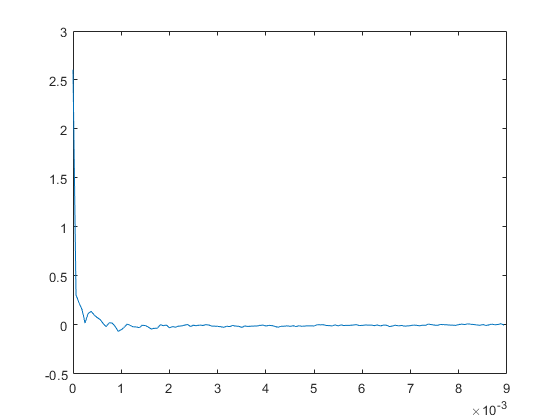

[Echo, Fs] = audioread('echo_sound.wav');
dt=1/Fs;
ninems = int16(0.009*Fs);
t = 0:dt:0.009-dt;
c = rceps(Echo);
[pks, Max] = findpeaks(c,'Threshold',0.1);
plot(t,c(1:ninems));

%D = Delta
D = Max(1)-1;



b=1;
a=[1 zeros(1, D-1) 0.8];
refirst_voice = filter(b, a, Echo);
audiowrite('refirst.wav', refirst_voice, Fs);